**Problem Setup: Airfoil Shape Optimization**

**Objective**: Maximize the lift-to-drag ratio for the airfoil at a specific angle of attack, to improve the efficiency of a UAV.

**Design Variables**: Shape parameters of the airfoil, such as:

- **Camber** (curvature of the airfoil): Specified as the ratio of the maximum distance from the chord line to the mean camber line over the chord length.  Low values are 0-0.01, medium, 0.02-0.04 and high is greater than 0.04.  Increased camber provides increased lift, but at the cost of additional drag.

- **Thickness** (ratio of chord thickness to chord length): The thickness-to-chord ratio si the maximum thickness of the airfoil to the chord length.  Thin airfoils (0.08-0.12) are suitable for high-speed, low-drag applications.  Thicker airfoils (0.12-0.15) provide greater structureal strength for manueverability and payload.

- **Chord Length** (distance from leading edge to trailing edge),

- **Angle of Attack** (orientation relative to airflow).  We will keep this constant at 5 degrees.

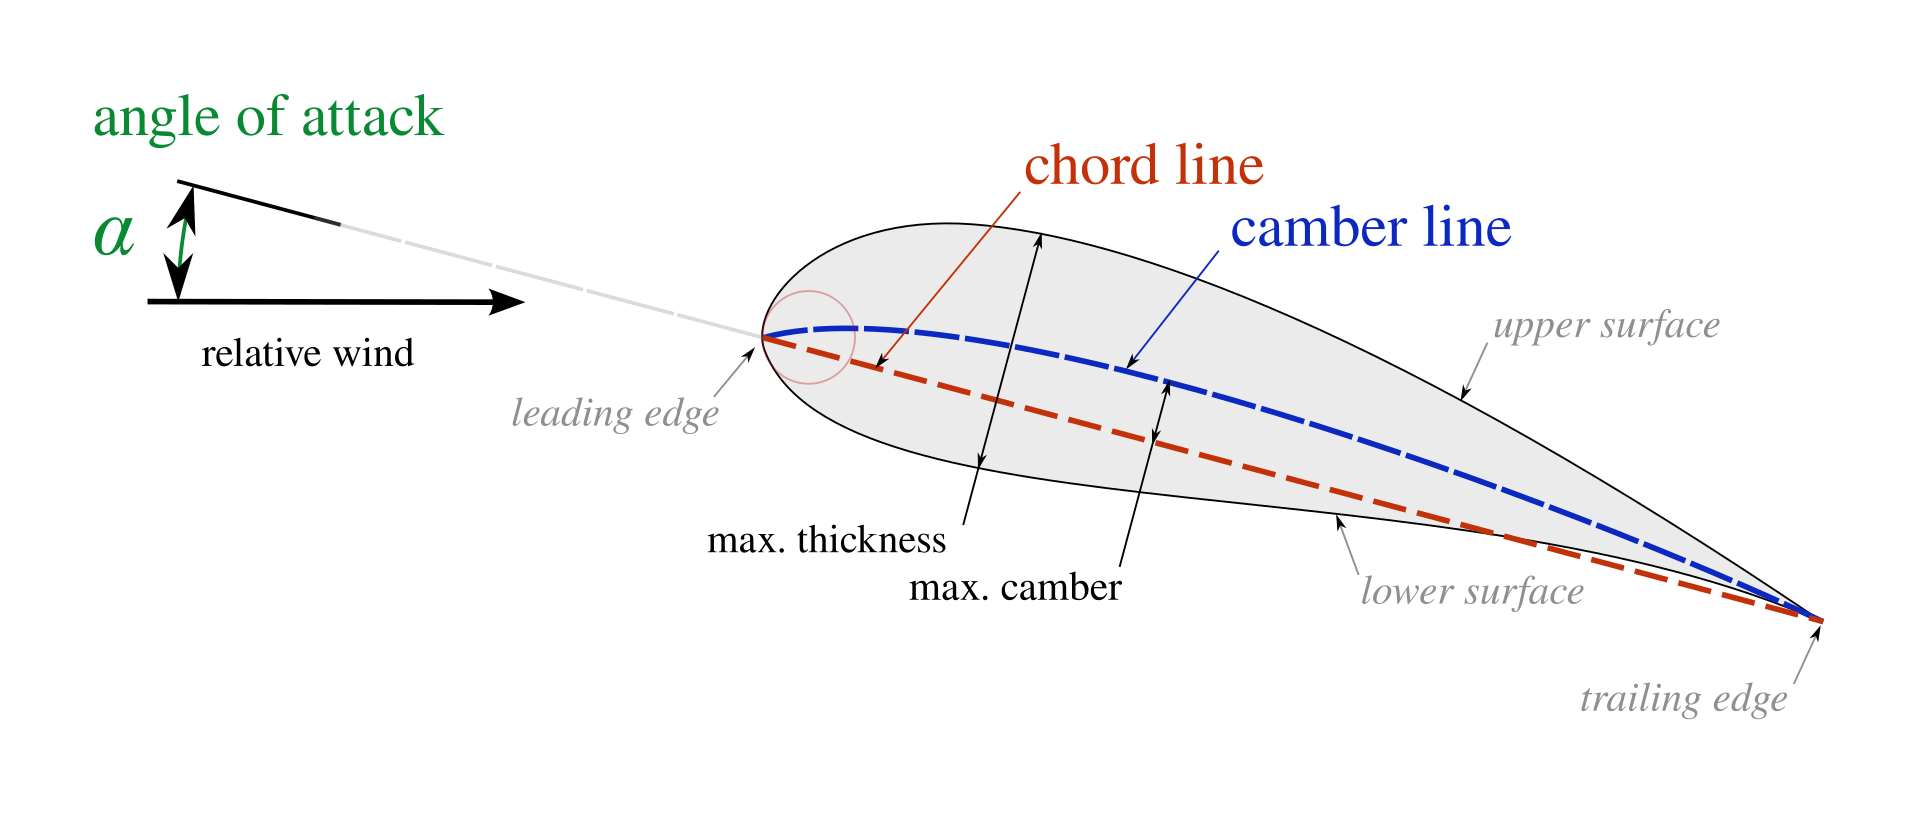

Choose AOA, $\alpha$, as 5 degrees for a UAV.

**Constraints**:

- **Structural Constraints**: Maximum allowable thickness or aspect ratio for manufacturing or material strength.

- **Performance Constraints**: Minimum lift and stability requirements.

**Defining the Cost Function**

The cost function here would involve simulating the aerodynamic performance of the airfoil for each combination of design variables and calculating the lift-to-drag ratio L/DL/DL/D.

- **Simulation-Based Cost Function**: Using aerodynamic simulation software (e.g., XFOIL or a built-in MATLAB CFD toolbox), calculate the lift and drag coefficients for each airfoil configuration and convert them to the lift-to-drag ratio. Alternatively, you could approximate the lift and drag with simplified analytical models.


$$L/D= \frac{C_L}{C_D}$$


where $C_L$ and $C_D$ are the lift and drag coefficients, respectively.

- **Objective Function**: 

Maximize $L/D$, or equivalently, **minimize the negative lift-to-drag ratio**:


$$f(\mathbf{x}) = -\frac{C_L(\mathbf{x})}{C_D(\mathbf{x})}$$


�where $\mathbf{x}$ is the vector of design variables (camber, thickness, chord length, etc.).

**Constraints Using Penalties**:

Apply a penalty if the airfoil fails to meet a minimum lift requirement for a specific application.

Add penalties for shape limitations or structural limits. For example, if the thickness-to-chord ratio exceeds a maximum allowable value $t_{\text{max}}$:


$$\text{penalty}_{\text{thickness}} = k_{\text{thickness}} \cdot \max(0, t - t_{\text{max}})^2$$


where $k_{\text{thickness}}$� is a large constant that discourages designs outside the feasible range.

**12-15%** might be more suitable to ensure structural integrity.

**uggested Values**:

- For a small reconnaissance UAV with a strong emphasis on endurance, a **10% thickness-to-chord ratio** could be ideal.

- For a tactical UAV requiring more payload capacity or additional onboard equipment, **12-15%** might be more suitable to ensure structural integrity.

**2. ****Aspect Ratio**

Aspect ratio ARARAR is the ratio of the square of the wingspan to the wing area. Higher aspect ratios are generally more efficient for generating lift with lower drag, which is beneficial for endurance and high-altitude flight, while lower aspect ratios offer better maneuverability.

AR=wingspan2wing areaAR = \frac{\text{wingspan}^2}{\text{wing area}}AR=wing areawingspan2�

- **Typical Range**: For UAVs, aspect ratios between **6 and 12** are common.

- **6 to 8**: Low to moderate aspect ratios in this range are used for UAVs that prioritize maneuverability and compact design over pure aerodynamic efficiency. These are typical in smaller, tactical UAVs that operate at lower altitudes or have agility requirements.

- **8 to 12**: Higher aspect ratios are beneficial for endurance UAVs, as they reduce induced drag, which is ideal for sustained high-altitude, long-duration flights.

- **Suggested Values**:

- For an endurance UAV, an aspect ratio of **10 to 12** will help minimize drag, supporting longer flight times and reduced fuel consumption.

- For tactical UAVs with more complex operational needs (e.g., shorter-range missions, agile flight), an aspect ratio closer to **6 to 8** could be more suitable, balancing stability and maneuverability.

**Summary of Suggested Constraints**

For a typical UAV:

- **Thickness-to-Chord Ratio**: Between **8% and 15%**, with a specific selection depending on the UAV’s mission (10-12% is a common balance).

- **Aspect Ratio**: Between **6 and 12**, with a choice based on desired endurance versus maneuverability.

**Additional Considerations**

- **Structural Constraints**: Thicker airfoils are structurally stronger, which can support higher payloads or resist aerodynamic stresses better. For UAVs with long wingspans, a slightly higher thickness-to-chord ratio may help prevent excessive wing bending.

- **Aerodynamic Constraints**: Higher aspect ratios benefit aerodynamic efficiency, but very high aspect ratios may require more rigid (and thus heavier) materials to prevent flexing.

Using these guidelines can provide a balanced starting point for designing UAV airfoils that are structurally sound and aerodynamically efficient.

**Implementing in MATLAB**

Here is a simple approximate model for aerodynamic coefficients, $C_L$ and $C_D$, as a function of the design variables, based on empirical relations:


$$C_L = 2 \pi \cdot \alpha \cdot Camber 
$$



$$C_D = C_{D_0} + k C_L^2$$


function [CL, CD] = calculateAerodynamicCoefficients(camber, thickness, chord, angle_of_attack)
    % Parameters for a simple model
    C_D0 = 0.01; % Parasitic drag coefficient
    k = 0.02;    % Induced drag factor, approximate
    
    % Convert angle of attack to radians
    alpha_rad = deg2rad(angle_of_attack);
    
    % Estimate lift and drag coefficients
    CL = 2 * pi * camber * alpha_rad;
    CD = C_D0 + k * CL^2;
end

function cost = airfoilCost(x)
    % Constants for penalty weights
    k_thickness = 1e5; % Penalty for thickness violations
    
    % Extract design variables
    camber = x(1);
    thickness = x(2);
    chord_length = x(3);
    % Fixed
    angle_of_attack = 5;
    
    % Simulate or approximate lift and drag coefficients
    [CL, CD] = calculateAerodynamicCoefficients(camber, thickness, chord_length, angle_of_attack);
    
    % Calculate the lift-to-drag ratio
    L_D_ratio = CL / CD;
    
    % Cost function to maximize L/D (or minimize -L/D)
    cost = -L_D_ratio;
    
    % Penalty for failing minimum lift requirement
    min_lift_coefficient = 0.4;
    if CL < min_lift_coefficient
        cost = cost + 1e6 * (min_lift_coefficient - CL)^2;
    end
    
    % Penalty for exceeding thickness constraint
    max_thickness = 0.15;
    if thickness > max_thickness
        cost = cost + k_thickness * (thickness - max_thickness)^2;
    end

optimized_x =     1.2896    0.1469    4.7014


    if (camber<0) | thickness < 0  | chord_length <0

CL = 0.7071

CD = 0.0200

        cost = 1e6;
    end
end


x0 = [0.05, 0.12, 1]; % Initial guesses for camber, thickness, chord

optimized_x = fminsearch(@airfoilCost, x0)
[CL, CD] = calculateAerodynamicCoefficients(optimized_x(1), optimized_x(2), optimized_x(3), 5)

**Evaluating the Results**

- **Optimized Shape Parameters**: `optimized_x` gives the values for camber, thickness, chord length, and angle of attack that achieve the best L/DL/DL/D ratio within the defined constraints.

- **Verify Constraints**: Ensure that the final design meets the lift, thickness, and other requirements. If not, consider adjusting the penalty terms or constraints.